# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 16-Dec-2022 19:23:10

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 26);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["var_min_air_gap", "var_c_r", "var_c_a", "var_h_C", "var_r_Cout", "var_D_w", "var_t_cfr", "var_t_cfa", "var_t_mba", "var_t_mta", "var_r_A", "var_r_cham", "var_h_cham", "var_t_shell", "var_PR", "var_CSF", "var_h_air", "var_mu", "var_mu0", "var_CWCC", "var_erc", "Nturns", "P", "Ks", "orifice_opening_t", "orifice_closing_t"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
designoptions = readtable("C:\Users\kutla\Documents\GitHub\thesis\design_options.csv", opts);

## Clear temporary variables

clear opts


total_time = designoptions.orifice_opening_t + designoptions.orifice_closing_t;
fastest = find(min(total_time) == total_time)

fastest = 2

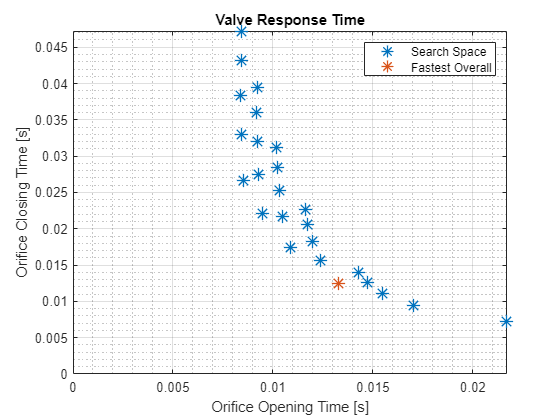

plot(designoptions.orifice_opening_t,designoptions.orifice_closing_t,designoptions.orifice_opening_t(fastest),designoptions.orifice_closing_t(fastest),"LineStyle","none","Marker","*","MarkerSize",10,LineWidth=1)
xlim([0 inf]),ylim([0 inf])
grid on, grid minor
xlabel('Orifice Opening Time [s]'),ylabel('Orifice Closing Time [s]'),title('Valve Response Time'),legend('Search Space','Fastest Overall')